**Run JSNMF algorithm on mouse brain (RNA+H3K4me3, paired-Tag) data**

**Load data**

addpath('../data')
load('h3k4me3_5k_10k.mat')
num_clu = length(unique(label));

**Marker genes and housekeeeping genes are given by user**

marker_genes = ["Dnah12"; "Cfap299";'Flt1'; 'Slco1a4'; 'Inpp5d'; 'Hexb'; 'Slc1a3'; 'Atp1a2'; 'Slc1a2'; 'Gpc5'; ...
    'Prr5l'; 'Plp1'; 'Rnf220'; 'Lhfpl3'; 'Cacng4'; 'Erbb4'; 'Kcnc2'; 'Reln'; 'Grin3a'; 'Adarb2'; 'Fam19a2'; ...
    'Ahcyl2'; 'Gm32647'; 'Shisa6'; 'Epha6'; 'Galnt14'; 'Hs3st4'; 'Tshz2'; 'Fam19a1'; 'Il1rapl2'; 'Cdh12'; 'Rgs6';...
    'Lingo2'; 'Prr16'; 'Zfp804b'; 'Pex5l'; 'Gm26883'; 'Cdh18'; 'Gm28928'; 'Galntl6'; 'Spag16'; 'Cfap43'; 'Wdr49';...
    'Ebf1'; 'Mecom'; 'Ptprb'; 'Tgfbr1'; 'Zfhx3'; 'Apbb1ip'; 'Gpc5'; 'Plpp3'; 'Slc1a2'; 'Igsf8'; 'St18'; 'Mog'; 'Mag';...
    'St18'; 'Mbp'; 'Vcan'; 'Tnr'; '6030443J06Rik'; 'Nxph1'; '6330411D24Rik'; 'Kcnmb2'; 'Grip1'; 'Gm45341'; 'Gm45455';...
    'Grip1'; 'Trpm3'; 'Rfx3'; 'Dgkh'; 'Hs3st4'; 'Ryr3'; 'Hs6st3'; 'Gm2164'; 'Grik4'; 'Cpne7'; 'Gm2164'; 'Ryr3';...
    'Hs6st3'; 'Sdk1'; 'Foxp2'; 'Garnl3hrm2'; 'Grm8'; 'Vwc2l'; 'Olfm3'; 'Grik1 Gm2164'; 'Gm28928'; 'Sgcz'; 'Prr16'; ...
    'Chrm3'; 'Pdzrn3'; 'Kcnq5'; 'Unc5d'; 'Car10'; 'Pcdh15'; 'Nrg1']; 
marker_genes = unique(marker_genes);
load('housekeeping_genes.mat')
housekeeping_genes = hp_genes;

**Preparing for RAGI**

load('h3k4me3_rna_RAGI.mat')
genes = genes_h3k4me3; data = rna_h3k4me3;
[genes_h3k4me3, rna_h3k4me3] = rna_ragi(barcodes, share_bd, genes, RNA,1);

[~,~,ind1] = intersect(marker_genes,genes,'stable');
[~,~,ind2] = intersect(housekeeping_genes,genes,'stable');

**Run JSNMF**

**Parameter seletion** 

addpath('../codes')
addpath('../external')
[alpha,gamma,Inits] = parameter_selection(X1,X2,label);

**Start time**

tic
[W1,W2,H1,H2,S,iter,objs] = jsnmf(X1,X2,alpha,gamma,Inits);

number of iteration:10  obj:2167309.0214
number of iteration:20  obj:2160203.2657
number of iteration:30  obj:2157360.4942
number of iteration:40  obj:2155750.9988
number of iteration:50  obj:2154672.8747
number of iteration:60  obj:2153795.968
number of iteration:70  obj:2152994.5733
number of iteration:80  obj:2152529.4533
number of iteration:90  obj:2152224.5205
converged!


disp('JSNMF runtime:');

JSNMF runtime:


toc

Elapsed time is 83.680113 seconds.


**Evaluating peformance**

% KNN on S
A = Wtrim(S,50); 
% implement louvain clustering
[clust,~,~] = getNCluster(A,num_clu,0,3,20); 
if length(unique(clust))== num_clu
   [ac, nmi_value, ~] = CalcMetrics(label, clust);
   [ave_mk_gini, ave_hk_gini, difgini] = RAGI(data,ind1,ind2,clust);
else
% using spectral clustering instead if number of clusering doesn't equals to the pointed number
   [~, clust, ~] = SpectralClustering(A, num_clu); 
   [ac, nmi_value, ~] = CalcMetrics(label, clust);   
   [ave_mk_gini, ave_hk_gini, difgini] = RAGI(data,ind1,ind2,clust);
end

ac: 0.8633	367/2684	nmi:0.8401	


ave_marker_gene: 0.4258	ave_hk_gini:0.1932	diff_gini:0.2326	


**Downstream analysis including visualization**

**visualization on S obtained from JSNMF**

Parallelizing UMAP with MATLAB's 8 assigned logical cores for nn_descent_tasks, sgd_tasks


 Running basic (ub) reduction, v2.1.3
(ub=basic, us=supervised, ubt=template, ust=supervised template)


UMAP(method=MEX, n_neighbors=12, n_components=2, metric='precomputed', n_epochs=[], learning_rate=1, init=spectral, min_dist=0.68, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=0.341583914561778, b=1.53965606727517, randomize=true, target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='precomputed', dist_args=[]


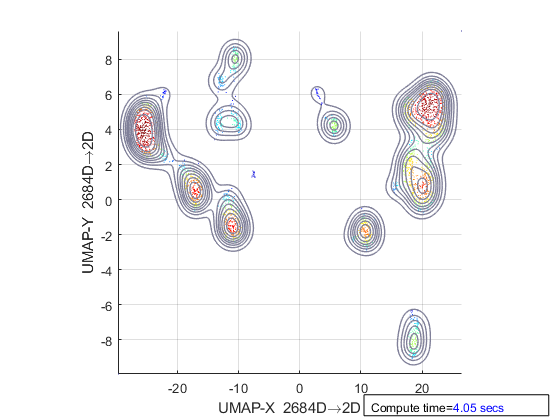

UMAP reduction finished (cost 4.07 secs)
 Finished basic (ub) reduction


% load UMAP package
addpath('../umapFileExchange/umap') 
addpath('../umapFileExchange/util')

term = '.'; 
label_name = label_h3k4me3(:,2);
label_name = strrep(label_name,'_','\_');
colors = generateColors(max(length(unique(label_name))),length(unique(term)));

D_jsnfm = 1-S; D_jsnfm = D_jsnfm-diag(diag(D_jsnfm));
[reduction_jsnmf, ~, ~, ~] = run_umap(D_jsnfm,'metric','precomputed','min_dist',0.68,'n_neighbors',12); 

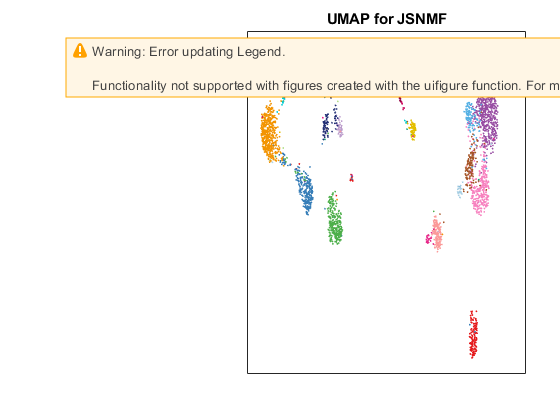

gscatter(reduction_jsnmf(:,1),reduction_jsnmf(:,2),label_name,colors,[],4); 
set(gca,'xtick',[],'ytick',[]);
title('UMAP for JSNMF')

legend('Location','westoutside','Box','off','FontSize',9.5); 
legendmarkeradjust(16)
legend('boxoff') 